1. Implementati o rutina pentru calculul valorilor polinomului de interpolare Lagrange cand se dau punctele, nodurile si valorile functiei in noduri

 nodes, nodevals, point 

interpolareLagrange([3 4 5], [7 6 3], 3.8)

ans = 6.3600

2. Reprezentati grafic polinoamele fundamentale cand se dau gradul si nodurile.

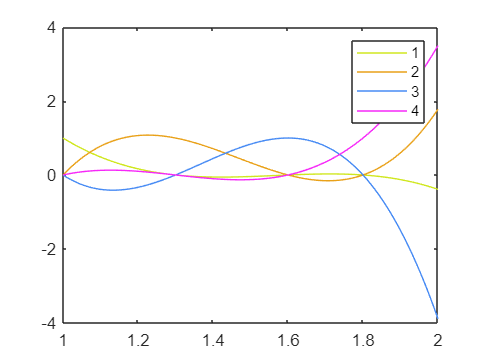

nodes = [1 1.3 1.6 1.8];
m = 4;

labels = {};
for k = 1 : m
    t = 1 : 0.01 : 2;
    p = evalPolFundamentalMultiplePoints(nodes, k, t);
    labels = [labels num2str(k)];
    plot(t, p, 'color', rand(1,3))
    hold on;
end
legend(labels);
hold off;

3. Reprezentati pe acelasi grafic f si Lmf 

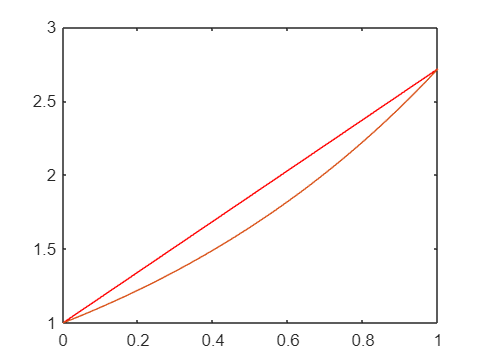

nodes = [0, 1];
nodevals = exp(nodes);

t = 0 : 0.01 : 1;
res = interpolareLagrangeMultiplePoints(nodes, nodevals, t);

plot(t, res, 'r');
hold on;

resexp = exp(t);
plot(t, resexp);
hold off;

4. Dandu-se x, f, m si nodurile, aproximati f(x) utilizand interpolarea Lagrage  

interpLagrFdat(1.2, @exp, 3, [1.1 1.4 1.6])

ans = 3.3151

5. Implementati metoda baricentrica

interpolareLagrangeBaricentrica([3 4 5], [7 6 3], 3.8)

ans = 6.3600

1.  Aproximati populatia din SUA in 1975 si 2018

x = [1900   1910   1920    1930    1940    1950    1960    1970    1980];
y = [75995 91972 105711 123203 131669 150697 179323 203212 226505];

% Pentru estimarea populatiei din anul 1975 am ales datele din 1900 pana in
% 1990. Rezultatul este 215759, cu marja de eroare 0.22 fata de rezultatul
% recensamantului din 1975, care a fost de 21597
fprintf("Practic 1: ");

Practic 1: 

fprintf("Populatia in 1975");

Populatia in 1975

fprintf("%f",interpolareLagrangeBaricentrica(x, y, 1975));

215759.805115


x = [1990    2000    2010];
y = [249633 281422 308786];

%Pentru anul 2018 am ales datele din 1990 pana in 2010, deoarece este
%nevoie de valori cat mai apropiate pentru a ajunge la un rezultat
%favorabil. Rezultatul este 327491, cu o marja de eroare de aproximativ
%0.2 fata de rezultatul actual din 2018, 3272
fprintf("Populaatia in 2018");

Populaatia in 2018

fprintf("%f",interpolareLagrangeBaricentrica(x, y, 2018));

327491.200000

2. Fie f(x) = e^(x^2-1). Aproximati f(1:25) utilizand valorile lui f in 1, 1.1, 1.2, 1.3 si 1.4 si dati

o delimitare a erorii.

f = @(x)exp(x.^2 - 1);
fprintf("Practic 2: ");

Practic 2: 

interpLagrFdat(1.25, f, 4, [1 1.1 1.2 1.3 1.4])

ans = 1.7557

fprintf("Real: %f", exp(1.25.^2 - 1));

Real: 1.755055


% concluzia e ca eroarea este de 0.000645

3. Aproximat sqrt(115) cu 3 zecimale exacte prin interpolare Lagrange

% Am ales ca valoriel nodurilor sa fie cuprinse intre 100 si 121, deoarece
% 115 este cuprins intre aceste patrate perfecte consecutive. Valoarea lui
% sqrt(115) este aproximativ egala cu 10.7238

% Pentru aproximarea radicalului cu 3 zecimale exacte, am ales ca noduri
% cele 2 capete si o valoare apropiata de 115, 113. Pentru interpolarea
% Lagrange cu m=3, rezultatul va fi 10.7239
fprintf("Practic 3: ");

Practic 3: 

disp("--- m=3 ---")

--- m=3 ---


xs = interpLagrFdat(115, @sqrt, 3, [100 113 121]);
disp(xs);

   10.7239



s = sqrt(115);
disp(s);

   10.7238





% Pentru a ajunge la un rezultat cat mai exact, este nevoie de adaugarea
% mai multor noduri si impliciit marirea gradului. De exemplu, pentru
% nodurile [100 107 117 121] si m=4, rezultatul interpolarii devine 10.7238
disp("--- m=4 ---")

--- m=4 ---


xs = interpLagrFdat(115, @sqrt, 4, [100 107 117 121]);
disp(xs);

   10.7238



s = sqrt(115);
disp(s);

   10.7238

